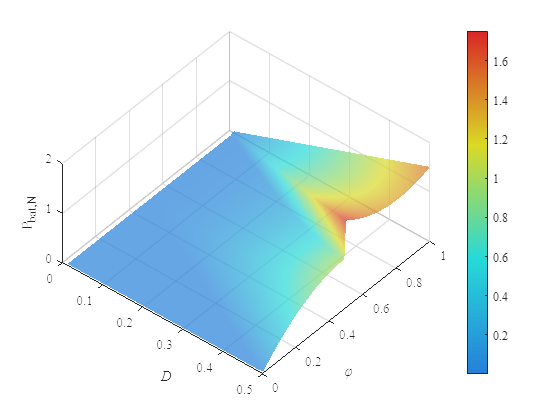

% Given parameters 
n = 4;
V_bat = 50;
f_s = 100e3;
L_k = 30e-6;
V_dc = 800;
L = 80e-6;
I_ZVS2 = 0;
M = 1;
alpha = 1e-4;  % Smoothing constant to avoid discontinuities
gamma = 1e-3;  % Small constant to avoid zero outputs in P_bat

% Create a mesh grid for D and varphi
D = linspace(0.01, 0.5, 100);  % D in [0, 0.5]
varphi = linspace(0.01, 1, 100); % varphi in [0, 1]
[D_grid, varphi_grid] = meshgrid(D, varphi);  % mesh grid for D and varphi

% Calculate P_N (normalized power) and I_N
P_N = (n * V_bat * V_dc) / (8 * f_s * L_k);
IN = n * V_bat / (4 * f_s * L_k);

% Initialize P_bat
P_bat = zeros(size(D_grid));

% Calculate sigma
sigma = 2 * D_grid.^2 + 4 * D_grid .* varphi_grid - D_grid;

% Loop over each grid point and calculate P_bat
for i = 1:numel(D_grid)
    D_val = D_grid(i);
    varphi_val = varphi_grid(i);
    
    % Apply the conditions and compute P_bat
    if varphi_val < 0.5 - D_val
        P_bat(i) = sigma(i) + gamma - (2 * (n * IN * (-M - 2 * D_val + 4 * M * varphi_val + 4 * D_val * M) + I_ZVS2) * D_val * V_bat)/P_N ;
    elseif varphi_val >= 0.5 - D_val && varphi_val < 0.5
        P_bat(i) =  (-sigma(i) + 2 * D_val - (2 * varphi_val - 1)^2) + gamma - (2 * (n * IN * (3 * M - 2 * D_val - 4 * M * varphi_val - 4 * D_val * M) + I_ZVS2) * D_val * V_bat)/P_N;
    elseif varphi_val >= 0.5 && varphi_val < 1 - D_val
        P_bat(i) =  (-sigma(i) + 2 * D_val) + gamma - (2 * (n * IN * (3 * M - 2 * D_val - 4 * M * varphi_val - 4 * D_val * M) + I_ZVS2) * D_val * V_bat)/P_N;
    else
        P_bat(i) =  (sigma(i) - 4 * D_val + 4 * (varphi_val - 1)^2) + gamma - (2 * (n * IN * (2 * D_val - M + varphi_val - 4) + I_ZVS2) * D_val * V_bat)/P_N;
    end
end

% Plot the results
figure;
surf(D_grid, varphi_grid, P_bat,'FaceAlpha', 0.7);

% Set color map and properties
set(gca, 'FontName', 'Times New Roman');

% Define color resolution
n = 256;
cmap = [linspace(0, 0, n/4)', linspace(0.5, 1, n/4)', linspace(1, 1, n/4)'; ...
        linspace(0, 1, n/4)', linspace(1, 1, n/4)', linspace(1, 0, n/4)'; ...
        linspace(1, 1, n/4)', linspace(1, 0, n/4)', linspace(0, 0, n/4)']; % Blue to Green to Yellow to Red
gray_level = 0.5; % Adjust the saturation towards gray
desaturated_cmap = cmap * 0.7 + gray_level * (1 - 0.7); % Linear interpolation
colormap(desaturated_cmap);
colorbar;

% Smooth shading
shading interp;

% Set view and grid
view(40,60); % Set view angle
grid on;
hold on;

xlabel('\it{D}');
ylabel('\it{φ}');
zlabel('P_{bat,N}');

colorbar;